% Parámetros del modelo
d = 0.8; 
R = 0.1; 
w_max = 15;  
Tw = 0.12;  

motor_i = Motor(Tw, w_max);
motor_d = Motor(Tw, w_max);
model = DiffVehicle(d, R, motor_i, motor_d);

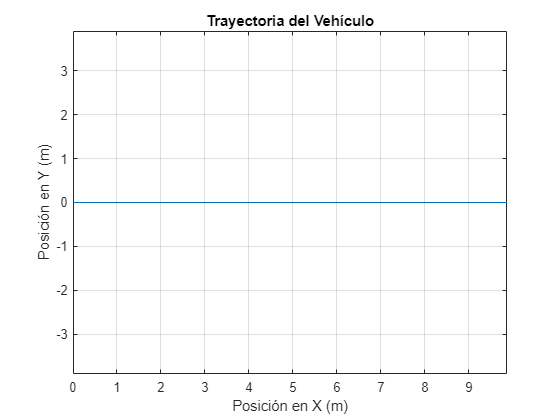

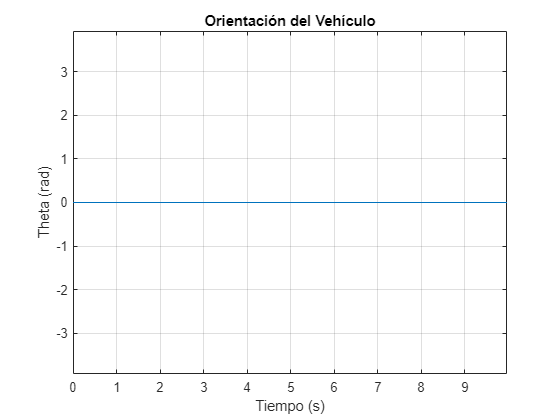

% Simulación
ts = 25/1000; % Tiempo de muestreo (s)
T = 10; % Tiempo total de simulación (s)

% Experimento 1: trayectoria recta
[x, y, theta] = model.simulate(10, 10, ts, T);
model.plot(x, y, theta, ts);

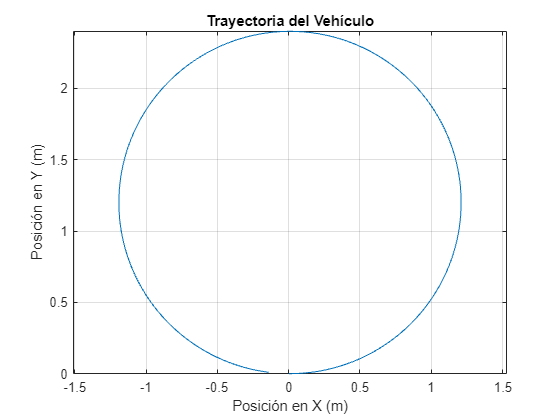

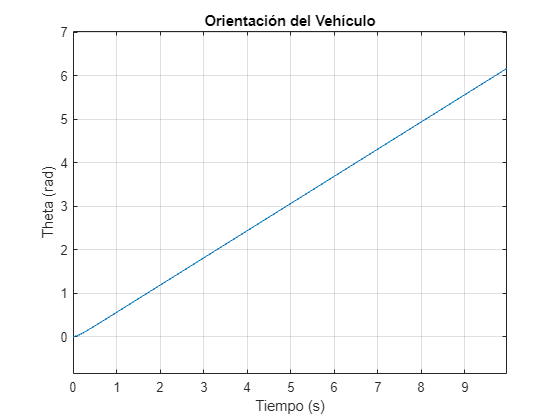

% Experimento 2: giro izquierda
[x, y, theta] = model.simulate(5, 10, ts, T);
model.plot(x, y, theta, ts);

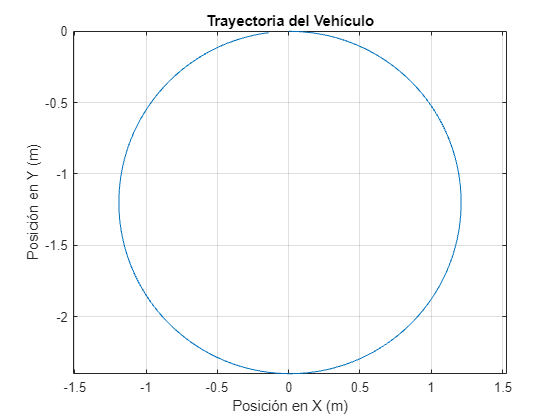

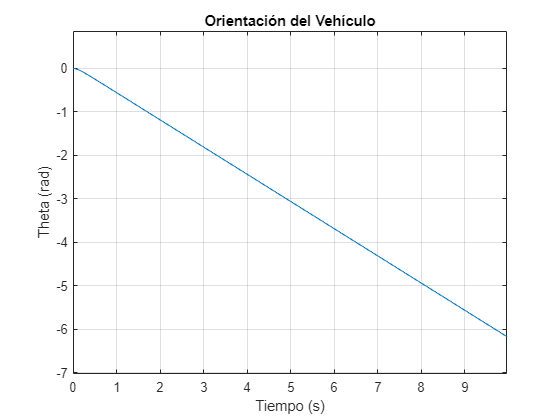

% Experimento 3: giro derecha
[x, y, theta] = model.simulate(10, 5, ts, T);
model.plot(x, y, theta, ts);

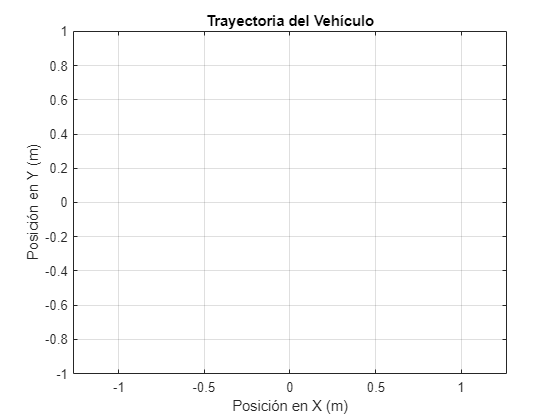

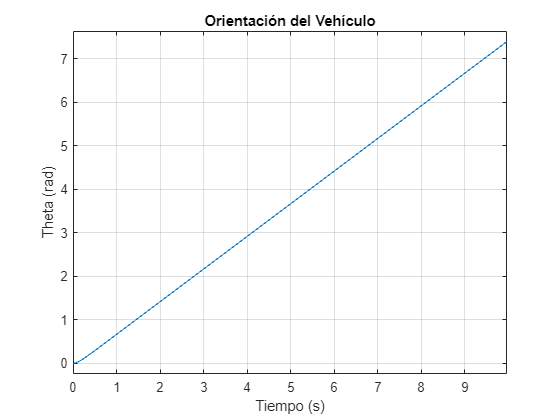

% Experimento 4: velocidad nula
[x, y, theta] = model.simulate(-3, 3, ts, T);
model.plot(x, y, theta, ts);